clc;clear all;close all;
M=1;
m=1;
l=1;
g=9.81;
syms ddth dth th ddx dx x u
Eq(1)=m*l*ddth+m*cos(th)*ddx-m*g*sin(th);
Eq(2)=m*l*cos(th)*ddth+(M+m)*ddx-m*l*dth^2*sin(th)-u;
SS=solve(Eq,[ddth;ddx]); %---> Aki se optiene ddth y ddx



%%1er paso Linealizar
syms x[4 1]
syms u t

xd=[0;pi;0;0];
ud=0;
f = cart(t,x,u) % planta

$$f = \left(\begin{array}{c} x_{3}\\ x_{4}\\ -\frac{100\,\sin\left(x_{2}\right)\,{x_{4}}^{2}+100\,u-981\,\cos\left(x_{2}\right)\,\sin\left(x_{2}\right)}{100\,{\cos\left(x_{2}\right)}^{2}-200}\\ \frac{50\,\cos\left(x_{2}\right)\,\sin\left(x_{2}\right)\,{x_{4}}^{2}-981\,\sin\left(x_{2}\right)+50\,u\,\cos\left(x_{2}\right)}{50\,{\cos\left(x_{2}\right)}^{2}-100} \end{array}\right)$$


Ajac=jacobian(f,x);
A=double(subs(Ajac,[x;u],[xd;ud]))

A =          0         0    1.0000         0
         0         0         0    1.0000
         0   -9.8100         0         0
         0  -19.6200         0         0



Bjac=jacobian(f,u);
B=double(subs(Bjac,[x;u],[xd;ud]))

B =      0
     0
     1
     1



Q=diag([50 1000 0.1 0.1]);
R=0.0001;
K=lqr(A,B,Q,R)

K = 1.0e+03 *

    0.7071    2.6814    0.6248   -0.5311



x0=[-1;0;0;0]

x0 =     -1
     0
     0
     0


[T,X]=ode45(@(t,x)cart(t,x,control(x,K,xd,ud)),[0 8],x0)

T =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


X =    -1.0000         0         0         0
   -1.0000   -0.0000    0.0001   -0.0001
   -1.0000   -0.0000    0.0001   -0.0001
   -1.0000   -0.0000    0.0002   -0.0002
   -1.0000   -0.0000    0.0002   -0.0002
   -1.0000   -0.0000    0.0005   -0.0005
   -1.0000   -0.0000    0.0007   -0.0007
   -1.0000   -0.0000    0.0010   -0.0010
   -1.0000   -0.0000    0.0012   -0.0012
   -1.0000   -0.0000    0.0025   -0.0025


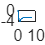

plot(T,X(:,2))

## Anima

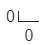

figure
l=0.5;
h1=line;hold on
h2=line;

for i=1:length(T)
    x_i=X(i,1);
    th_i=X(i,2);
    delete(h1);delete(h2);
    h1=plot([x_i x_i+l*sin(th_i)],[0 l*cos(th_i)],'bo-');
    h2=plot(x_i+0.2*[-1 1 1 -1 -1],0+0.1*[-1 -1 1 1 -1],'r-');
    axis([-2 2 -2 2])
    pause(0.05);
end

function u=control(x,K,xd,ud)
    u=ud-K*(x-xd);
end

function dx=cart(t,x,u)
    %x = [  x;
    %      th;
    %      dx;
    %     dth; ]

    th=x(2);dth=x(4);

    dx=[x(3);
        x(4);
        -(100*sin(th)*dth^2 + 100*u - 981*cos(th)*sin(th))/(100*(cos(th)^2 - 2));
        (50*cos(th)*sin(th)*dth^2 - 981*sin(th) + 50*u*cos(th))/(50*(cos(th)^2 - 2))];
end